%close all
clear;  
ccc='%3A'; 
%---setting
expri='test39';  
%year='2007'; mon='06'; s_date='01';  s_hr='12'; minu='00';
year='2018'; mon='06'; s_date='22';  s_hr='20'; minu='00';
infilenam='wrfout';  dom='01'; 

zi=9;  
indir=['E:/wrfout/expri191009/',expri];
%indir=['/HDD003/pwin/Experiments/expri_test/',expri];
outdir='E:/figures/expri191009/';

infile = [indir,'/',infilenam,'_d01_',year,'-',mon,'-',s_date,'_',s_hr,ccc,minu,ccc,'00'];
% qv = ncread(infile,'QVAPOR');
% u = ncread(infile,'U');
% v = ncread(infile,'V');
w = ncread(infile,'W');
% t = ncread(infile,'T'); t=t+300;

% ph = ncread(infile,'PH'); phb = ncread(infile,'PHB');
% z=(ph+phb)./9.81; 
%ti=20; zi=3;
%hgt= ncread(infile,'HGT');
% rc = ncread(infile,'RAINC');
% rsh = ncread(infile,'RAINSH');
% rnc = ncread(infile,'RAINNC');
% rain=rc+rsh+rnc;

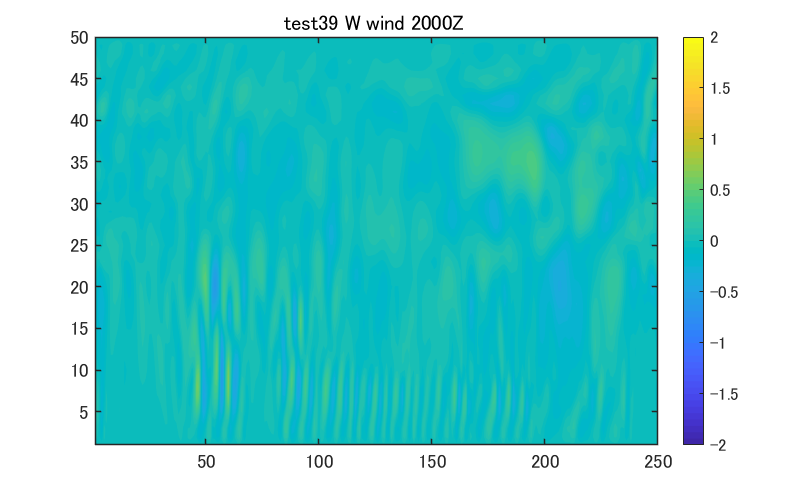

%---plot different variables
%  figure
%    contourf(u(:,:,zi)',20,'linestyle','none')
%    title([expri,' U wind ', s_hr,minu,'Z , zi=',num2str(zi)],'FontSize',15)
%    colorbar

%  figure
%    contourf(v(:,:,zi)',20,'linestyle','none')
%    title([expri,' V wind ', s_hr,minu,'Z , zi=',num2str(zi)],'FontSize',15)
%    colorbar
%  figure
%    contourf(w(:,:,zi)',20,'linestyle','none')
%    title([expri,' W wind ', s_hr,minu,'Z , zi=',num2str(zi)],'FontSize',15)
%    colorbar     
%  figure
%    contourf(qv(:,:,zi)',20,'linestyle','none')
%    title([expri,' qv ', s_hr,minu,'Z , zi=',num2str(zi)],'FontSize',15)
%    colorbar
%    %caxis([0.015 0.0175])
% figure
%   contourf(t(:,:,zi)',20,'linestyle','none')
%   title([expri,' potential temp  ', s_hr,minu,', zi=',num2str(zi)],'FontSize',15)
%   colorbar  
  %caxis([299 299.55])
% figure
%   contourf((z(:,:,zi,ti)+z(:,:,zi+1,ti))*0.5,20,'linestyle','none')
%   title([expri,' geopotential height, ti=',num2str(ti),', zi=',num2str(zi)],'FontSize',15)
%   colorbar  
%  figure('Position',[100 100 600 400])
%    contourf(rain(:,:)',20,'linestyle','none')
%    title([expri,'  rain  ', s_hr,minu,'Z  , zi=',num2str(zi)],'FontSize',15)
%    colorbar
   
 hf=figure('Position',[100 100 800 500]);  
   contourf(squeeze(w(:,100,:))',20,'linestyle','none')
   title([expri,' W wind ', s_hr,minu,'Z '],'FontSize',15)
   colorbar    
   caxis([-2 2])
   set(gca,'Fontsize',14,'linewidth',1.2)

   %print(hf,'-dpng',[outdir,expri,'_w-prof_',s_hr,minu,'.png'])   
